# Control y Programación de Robots (GIERM)

## Práctica 2, Ejer1: Localización basada en LSE

## Código para Alumnos

This program implements a Least Square Error (LSE) Localization (only positioning)  in a Map with N Landmarks. The robot is equipped with a range-only sensor which measures the distance to all the landmarks in the map. The optimization starts from the robot odometry which is randomly generated from the True Pose.

Javier Monroy & Cipriano Galindo, Oct. 2022

clc;
clear all; 
close all;
addpath(['auxmatlab/aux_functions'], 'auxmatlab/aux_functions_prob', 'p01lab01');

## PARAMETERS

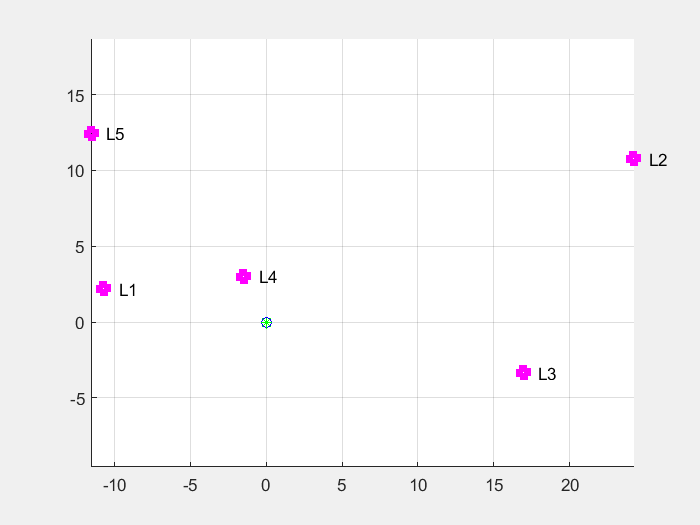


% 1 Crea un mapa con la ubicación aleatoria (posición en plano X,Y) de 5 landmarks
% 2 Establece la varianza de las distancias var_d y crea la matriz R
% 3 Define la matriz U de covarianzas (medio metro y medio grado)
% 4 Inicializa el estado de z, h, xTrue, xEst, xOdom y jH
% 5 Establece parámetros para el bucle interno LSE - Gauss-Newton
% 6 Dibuja los landmarks y la posición inicial del robot

% 1 Map
nLandmarks = 5;
mapSize = 50;                               % Lengh in meters
Map = mapSize*rand(2,nLandmarks)-mapSize/2; % Landmarks uniformly distributed in map

% 2 Noise in measurements
var_d = 0.05^2;                      % variance of the range measurement [noise per meter]
R = zeros(nLandmarks,nLandmarks);   % covariance matrix of the landmarks observations (noise depends on distance)

% 3 Control Action (square) & noise in robot movement
inc_x = 1;                  % the robot moves 1 m. at each step, but affected by noise
inc_phi = pi/2;             % the robot turns 90 deg at certain points
u_stdx = 0.5;
u_stdy = 0.5;
u_stdphi = 0.5*pi/180;
U = diag([u_stdx,u_stdy,u_stdphi]).^2;  % covariance of the odometry noise

% 4 System state definition
z = zeros(nLandmarks,1);    % observations to all landmarks
h = zeros(nLandmarks,1);    % predicted observations (sensor model)
xTrue = zeros(3,1);         % Simulated true pose of the robot (in this case xOdom affected by noise)
xEst = zeros(3,1);          % pose estimated by the LSE method
xOdom = zeros(3,1);         % position given by odometry (noise free)
jH = zeros(nLandmarks,2);   % jacobian of the observation function for all the landmarks
                            % jH has 2 columns because we only consider
                            % (x,y), not orientation

% 5 Parameters for the Gauss-Newton optimization loop (iterative)
nIteration = 100;
tolerance = 1.0e-09;  

% 6 Initial Graphics
figure(1);
set(gcf,'Visible','on');    % pup-up window
hold on; 
grid on; 
axis equal;
% plot landmarks (magenta squares)
plot(Map(1,:),Map(2,:),'sm','LineWidth',4);
% Plot Labels
for k = 1:size(Map,2)
    text( Map(1,k)+1,Map(2,k), sprintf('L%d',k) );
end
% plot robot positions (no orientation)
plot(xTrue(1),xTrue(2),'bo');   % Ground Truth (with Noise and the one we want to estimate)
plot(xOdom(1),xOdom(2),'r.');   % Odometry or ideal (Noise-free)
plot(xEst(1),xEst(2),'g*');     % the last estimation using LSE is plot in green

## MAIN LOOP

incr =    -0.0095
    0.2717


incr =     0.0001
    0.0035


incr = 1.0e-05 *

    0.3024
   -0.1036


incr = 1.0e-07 *

    0.0882
    0.1621


incr = 1.0e-10 *

    0.4024
    0.3356


incr =     0.2621
   -0.4258


incr = 1.0e-03 *

   -0.4760
    0.7471


incr = 1.0e-05 *

    0.2768
    0.5716


incr = 1.0e-06 *

    0.0545
    0.1118


incr = 1.0e-08 *

    0.1069
    0.2192


incr = 1.0e-10 *

    0.2095
    0.4296


incr =     0.7251
    0.1960


incr =    -0.0019
    0.0288


incr = 1.0e-03 *

    0.1083
    0.4386


incr = 1.0e-05 *

    0.1790
    0.6291


incr = 1.0e-07 *

    0.2585
    0.9050


incr = 1.0e-08 *

    0.0372
    0.1302


incr = 1.0e-10 *

    0.0535
    0.1873


incr =     0.4941
    0.2811


incr =     0.0017
    0.0287


incr = 1.0e-03 *

    0.2533
    0.9356


incr = 1.0e-04 *

    0.0917
    0.3178


incr = 1.0e-05 *

    0.0314
    0.1085


incr = 1.0e-07 *

    0.1072
    0.3706


incr = 1.0e-08 *

    0.0366
    0.1266


incr = 1.0e-10 *

    0.1250
    0.4322


incr =     0.8190
    1.2172


incr =    -0.0225
    0.0935


incr = 1.0e-03 *

   -0.2529
   -0.6209


incr = 1.0e-05 *

    0.1167
    0.6032


incr = 1.0e-07 *

   -0.1109
   -0.5681


incr = 1.0e-09 *

    0.1045
    0.5351


incr =     0.9587
    1.7111


incr =    -0.0226
    0.1686


incr =     0.0000
    0.0020


incr = 1.0e-04 *

    0.0445
    0.2267


incr = 1.0e-06 *

    0.0563
    0.2817


incr = 1.0e-08 *

    0.0700
    0.3505


incr = 1.0e-10 *

    0.0871
    0.4362


incr =     0.9963
    1.7317


incr =    -0.0088
    0.1475


incr =     0.0005
    0.0039


incr = 1.0e-03 *

    0.0203
    0.1115


incr = 1.0e-05 *

    0.0589
    0.3198


incr = 1.0e-07 *

    0.1692
    0.9177


incr = 1.0e-08 *

    0.0486
    0.2634


incr = 1.0e-10 *

    0.1394
    0.7560


incr =     0.6587
    2.4720


incr =    -0.0152
    0.1772


incr =     0.0001
    0.0030


incr = 2×1
1.0e-04 *

    0.0716
    0.5675


incr = 2×1
1.0e-05 *

    0.0139
    0.1066


incr = 2×1
1.0e-07 *

    0.0261
    0.2001


incr = 2×1
1.0e-09 *

    0.0489
    0.3759


incr = 2×1
    0.9051
    2.9374


incr = 2×1
   -0.0196
    0.0377


incr = 2×1
1.0e-03 *

   -0.0144
   -0.1432


incr = 2×1
1.0e-06 *

   -0.0379
    0.3593


incr = 2×1
1.0e-08 *

    0.0055
   -0.1106


incr = 2×1
1.0e-11 *

   -0.0202
    0.3234


incr = 2×1
    1.7503
    2.9868


incr = 2×1
    0.0231
   -0.1603


incr = 2×1
   -0.0003
   -0.0011


incr = 2×1
1.0e-05 *

   -0.1184
   -0.7194


incr = 2×1
1.0e-07 *

   -0.0705
   -0.4722


incr = 2×1
1.0e-09 *

   -0.0457
   -0.3097


incr = 2×1
    1.4951
    2.9342


incr = 2×1
    0.0041
   -0.1653


incr = 2×1
1.0e-03 *

   -0.1620
    0.1724


incr = 2×1
1.0e-06 *

   -0.0226
   -0.3839


incr = 2×1
1.0e-08 *

    0.0197
    0.1088


incr = 2×1
1.0e-11 *

   -0.0611
   -0.3162


incr = 2×1
    1.9167
    2.9471


incr = 2×1
   -0.0200
   -0.3225


incr = 2×1
1.0e-03 *

   -0.9110
   -0.7481


incr = 2×1
1.0e-05 *

    0.0331
    0.1003


incr = 2×1
1.0e-08 *

   -0.0209
   -0.1365


incr = 2×1
1.0e-11 *

    0.0222
    0.1837


incr = 2×1
    1.9113
    2.8607


incr = 2×1
   -0.0328
   -0.3365


incr = 2×1
   -0.0009
   -0.0025


incr = 2×1
1.0e-05 *

    0.0307
   -0.8752


incr = 2×1
1.0e-07 *

    0.0186
   -0.3443


incr = 2×1
1.0e-09 *

    0.0074
   -0.1362


incr = 2×1
    3.0085
    2.1779


incr = 2×1
    0.0324
   -0.5208


incr = 2×1
   -0.0020
    0.0024


incr = 2×1
1.0e-05 *

    0.1447
   -0.7079


incr = 2×1
1.0e-07 *

   -0.0011
    0.2255


incr = 2×1
1.0e-10 *

   -0.0387
   -0.7324


incr = 2×1
    2.7014
    1.7452


incr = 2×1
    0.0340
   -0.3850


incr = 2×1
1.0e-03 *

   -0.9555
   -0.3479


incr = 2×1
1.0e-06 *

   -0.1014
    0.0414


incr = 2×1
1.0e-09 *

   -0.0313
    0.1428


incr = 2×1
    3.5396
    1.9580


incr = 2×1
    0.0829
   -0.5859


incr = 2×1
   -0.0013
    0.0006


incr = 2×1
1.0e-05 *

   -0.0575
    0.1410


incr = 2×1
1.0e-08 *

   -0.0434
    0.2756


incr = 2×1
1.0e-11 *

   -0.0585
    0.5265


incr = 2×1
    4.5616
    2.6848


incr = 2×1
    0.1509
   -0.9400


incr = 2×1
    0.0027
   -0.0039


incr = 2×1
1.0e-04 *

    0.0524
   -0.2143


incr = 2×1
1.0e-06 *

    0.0224
   -0.1075


incr = 2×1
1.0e-09 *

    0.1099
   -0.5349


incr = 2×1
    4.8701
    2.8577


incr = 2×1
    0.1727
   -0.9989


incr = 2×1
    0.0071
   -0.0125


incr = 2×1
1.0e-04 *

    0.1743
   -0.7958


incr = 2×1
1.0e-06 *

    0.0965
   -0.4690


incr = 2×1
1.0e-08 *

    0.0566
   -0.2756


incr = 2×1
1.0e-10 *

    0.0333
   -0.1620


incr = 2×1
    4.8413
    2.5708


incr = 2×1
    0.1718
   -0.8907


incr = 2×1
    0.0054
   -0.0102


incr = 2×1
1.0e-05 *

    0.0435
   -0.4499


incr = 2×1
1.0e-08 *

   -0.0853
   -0.2865


incr = 2×1
1.0e-11 *

   -0.0980
   -0.2663


incr = 2×1
    5.0109
    2.8651


incr = 2×1
    0.1961
   -0.8926


incr = 2×1
    0.0061
   -0.0166


incr = 2×1
1.0e-05 *

    0.0203
   -0.4554


incr = 2×1
1.0e-09 *

   -0.6583
   -0.5072


incr = 2×1
    4.4793
    3.5701


incr = 2×1
    0.2424
   -0.7595


incr = 2×1
    0.0011
   -0.0108


incr = 2×1
1.0e-04 *

   -0.0051
    0.5529


incr = 2×1
1.0e-06 *

    0.0078
   -0.3010


incr = 2×1
1.0e-08 *

   -0.0041
    0.1634


incr = 2×1
1.0e-11 *

    0.0222
   -0.8873


incr = 2×1
    5.2993
    3.2897


incr = 2×1
    0.2569
   -0.9649


incr = 2×1
    0.0051
   -0.0168


incr = 2×1
1.0e-03 *

   -0.0060
    0.1407


incr = 2×1
1.0e-05 *

    0.0077
   -0.1263


incr = 2×1
1.0e-07 *

   -0.0069
    0.1132


incr = 2×1
1.0e-09 *

    0.0061
   -0.1014


incr = 2×1
    5.0980
    3.4475


incr = 2×1
    0.2592
   -0.8587


incr = 2×1
    0.0011
   -0.0176


incr = 2×1
1.0e-05 *

    0.0915
    0.2625


incr = 2×1
1.0e-08 *

    0.0192
   -0.1314


incr = 2×1
1.0e-12 *

   -0.0692
    0.6724


incr = 2×1
    4.9330
    3.3875


incr = 2×1
    0.2400
   -0.7555


incr = 2×1
   -0.0003
   -0.0164


incr = 2×1
1.0e-04 *

    0.1131
   -0.7616


incr = 2×1
1.0e-06 *

    0.0448
   -0.3352


incr = 2×1
1.0e-08 *

    0.0198
   -0.1472


incr = 2×1
1.0e-11 *

    0.0868
   -0.6466


incr = 2×1
    4.7666
    4.4404


incr = 2×1
    0.2966
   -0.7547


incr = 2×1
   -0.0030
   -0.0153


incr = 2×1
1.0e-04 *

    0.0594
   -0.4074


incr = 2×1
1.0e-07 *

    0.0893
   -0.9501


incr = 2×1
1.0e-09 *

    0.0220
   -0.2216


incr = 2×1
    5.6468
    4.5547


incr = 2×1
    0.3552
   -0.9326


incr = 2×1
   -0.0049
   -0.0177


incr = 2×1
1.0e-04 *

   -0.0403
    0.5989


incr = 2×1
1.0e-06 *

    0.0186
   -0.2231


incr = 2×1
1.0e-09 *

   -0.0687
    0.8301


incr = 2×1
    5.3414
    4.1687


incr = 2×1
    0.2782
   -0.7332


incr = 2×1
   -0.0035
   -0.0147


incr = 2×1
1.0e-04 *

    0.0810
   -0.4098


incr = 2×1
1.0e-06 *

    0.0146
   -0.1055


incr = 2×1
1.0e-09 *

    0.0395
   -0.2701


incr = 2×1
    5.2539
    3.8352


incr = 2×1
    0.2258
   -0.6496


incr = 2×1
   -0.0035
   -0.0084


incr = 2×1
1.0e-04 *

   -0.0482
    0.1796


incr = 2×1
1.0e-07 *

    0.1000
   -0.4886


incr = 2×1
1.0e-09 *

   -0.0275
    0.1310


incr = 2×1
    5.4281
    3.9986


incr = 2×1
    0.2030
   -0.6674


incr = 2×1
   -0.0032
   -0.0096


incr = 2×1
1.0e-04 *

    0.0169
    0.1397


incr = 2×1
1.0e-07 *

   -0.0186
   -0.2107


incr = 2×1
1.0e-10 *

    0.0281
    0.3132


incr = 2×1
    5.8254
    4.7373


incr = 2×1
    0.2217
   -0.7488


incr = 2×1
   -0.0047
   -0.0115


incr = 2×1
1.0e-04 *

   -0.0544
    0.1021


incr = 2×1
1.0e-07 *

    0.0549
   -0.1793


incr = 2×1
1.0e-10 *

   -0.0964
    0.2870


incr = 2×1
    5.6833
    5.1754


incr = 2×1
    0.1714
   -0.7457


incr = 2×1
   -0.0037
   -0.0103


incr = 2×1
1.0e-04 *

    0.0141
    0.1957


incr = 2×1
1.0e-07 *

   -0.0477
   -0.3475


incr = 2×1
1.0e-10 *

    0.0728
    0.6412


incr = 2×1
    5.9582
    5.7939


incr = 2×1
    0.1417
   -0.8667


incr = 2×1
   -0.0046
   -0.0126


incr = 2×1
1.0e-04 *

   -0.0395
    0.1771


incr = 2×1
1.0e-07 *

   -0.0170
   -0.2401


incr = 2×1
1.0e-10 *

   -0.0321
    0.3563


incr = 2×1
    5.7816
    5.6315


incr = 2×1
    0.1179
   -0.8309


incr = 2×1
   -0.0047
   -0.0086


incr = 2×1
1.0e-04 *

   -0.0800
    0.3880


incr = 2×1
1.0e-06 *

    0.0310
   -0.1842


incr = 2×1
1.0e-09 *

   -0.1492
    0.8736


incr = 2×1
    5.8496
    4.5353


incr = 2×1
    0.0355
   -0.8361


incr = 2×1
   -0.0039
   -0.0111


incr = 2×1
1.0e-04 *

   -0.0618
    0.2685


incr = 2×1
1.0e-07 *

    0.1809
   -0.7846


incr = 2×1
1.0e-09 *

   -0.0529
    0.2292


incr = 2×1
    5.6150
    4.3477


incr = 2×1
   -0.0031
   -0.7085


incr = 2×1
   -0.0025
   -0.0081


incr = 2×1
1.0e-04 *

   -0.0190
    0.2179


incr = 2×1
1.0e-07 *

    0.0008
   -0.5466


incr = 2×1
1.0e-09 *

   -0.0029
    0.1409


incr = 2×1
    5.8852
    4.4914


incr = 2×1
   -0.0292
   -0.6337


incr = 2×1
   -0.0015
   -0.0091


incr = 2×1
1.0e-04 *

    0.0607
   -0.1069


incr = 2×1
1.0e-07 *

    0.0867
   -0.2196


incr = 2×1
1.0e-10 *

    0.1722
   -0.3962


incr = 2×1
    5.2914
    3.5193


incr = 2×1
   -0.0712
   -0.4272


incr = 2×1
   -0.0012
   -0.0035


incr = 2×1
1.0e-05 *

   -0.1098
    0.5588


incr = 2×1
1.0e-07 *

    0.0353
   -0.1246


incr = 2×1
1.0e-10 *

   -0.0852
    0.2891


incr = 2×1
    5.3696
    3.3570


incr = 2×1
   -0.0575
   -0.1660


incr = 2×1
1.0e-03 *

   -0.2156
   -0.1874


incr = 2×1
1.0e-06 *

   -0.0432
    0.3891


incr = 2×1
1.0e-08 *

    0.0292
   -0.1473


incr = 2×1
1.0e-11 *

   -0.1155
    0.5748


incr = 2×1
    7.2036
    1.6581


incr = 2×1
   -0.0655
   -0.1757


incr = 2×1
1.0e-03 *

   -0.4244
    0.2218


incr = 2×1
1.0e-05 *

    0.0147
   -0.3384


incr = 2×1
1.0e-07 *

   -0.0147
    0.3309


incr = 2×1
1.0e-09 *

    0.0143
   -0.3237


incr = 2×1
    7.1855
    0.8903


incr = 2×1
    0.0331
    0.4206


incr = 2×1
   -0.0028
   -0.0019


incr = 2×1
1.0e-04 *

   -0.0212
   -0.1709


incr = 2×1
1.0e-06 *

   -0.0111
   -0.1115


incr = 2×1
1.0e-09 *

   -0.0713
   -0.7232


incr = 2×1
    7.6166
   -0.4624


incr = 2×1
   -0.0178
    1.3698


incr = 2×1
   -0.0282
   -0.0341


incr = 2×1
    0.0001
    0.0010


incr = 2×1
1.0e-04 *

   -0.0399
   -0.2813


incr = 2×1
1.0e-06 *

    0.1116
    0.7885


incr = 2×1
1.0e-07 *

   -0.0313
   -0.2210


incr = 2×1
1.0e-09 *

    0.0877
    0.6196


incr = 2×1
    7.4140
   -1.6426


incr = 2×1
    0.1091
    2.1011


incr = 2×1
   -0.0062
    0.1440


incr = 2×1
   -0.0006
   -0.0027


incr = 2×1
1.0e-04 *

    0.0738
    0.4937


incr = 2×1
1.0e-06 *

   -0.1389
   -0.9203


incr = 2×1
1.0e-07 *

    0.0259
    0.1715


incr = 2×1
1.0e-09 *

   -0.0483
   -0.3197


incr = 2×1
    7.2401
   -2.4252


incr = 2×1
    0.1328
    1.9145


incr = 2×1
    0.0422
    0.2266


incr = 2×1
    0.0003
    0.0027


incr = 2×1
1.0e-04 *

    0.0347
    0.1388


incr = 2×1
1.0e-07 *

    0.1856
    0.7304


incr = 2×1
1.0e-09 *

    0.0978
    0.3848


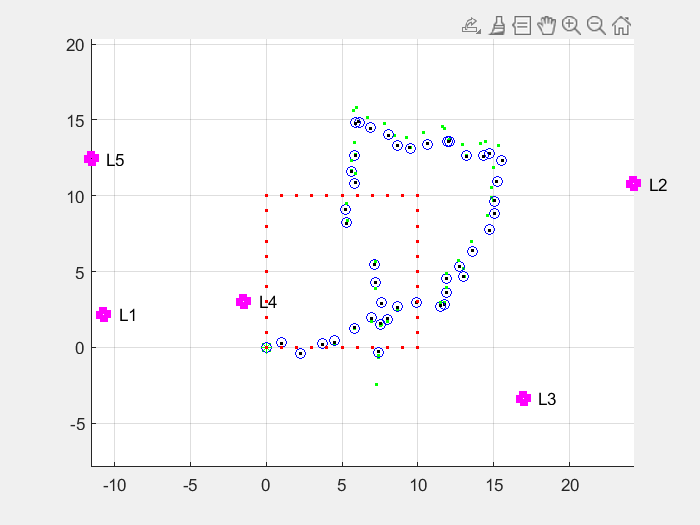

% 7 Inicializa el bucle externo iter/num_loops (44 movimientos) y errores
% 8 Para cada movimiento
%   9 Generar acción de control
%   10 Actualizar la odometría
%   11 Generar acción con ruido para simular comportamiento real
%   12 Actualizar la ground truth
%   13 Dibujar la posición odométrica y real del robot
%   14 Calcular z = distancia real a cada lanmark con ruido añadido
%   15 Inicializar xEst con posición de odometría
%   16 Para cada iteración de LSE
%       17 Calcular la distancia h y el jacobiano jH entre xEst y cada lanmark
%       18 Añadir R ruido dependiente z y calcular error=z-h
%       19 Calcular incremento de posición con la fórmula
%       20 Actualizar estimación de posición y graficarla


% 7
iter = 1;
num_loops = 44;    % number of times to execute the movement action
% initialization of the error vectors
loc_error = zeros(num_loops,1);
odo_error = zeros(num_loops,1);

% 8 Para cada movimiento
while iter < num_loops
    
    % 9 Generate Action (TO BE COMPLETED)
    if (mod(iter, 11)==0)
        u=[0, 0, inc_phi]';
    else
        u=[inc_x, 0, 0]';
    end

    % 10 Update xOdom: where the robot thinks it is (TO BE COMPLETED)
    xOdom = pose_comp(xOdom, u);
    
    % 11 Generate Noise sample & Noisy Action (TO BE COMPLETED)
    Sigma = diag([u_stdx,u_stdy,u_stdphi]);
    noise = Sigma*randn(3,1);
    uNoisy = pose_comp(u, noise);

    % 12 Update xTrue: This is the actual, unknown position of the robot (TO BE COMPLETED)
    xTrue = pose_comp(xTrue, uNoisy);
        
    % 13 Plot robot positions (without orientation)
    plot(xTrue(1),xTrue(2),'bo');   % Real Position (Ground Truth with Noise)
    plot(xOdom(1),xOdom(2),'r.');   % Odometry or ideal (Noise-free)
  
    % 14 SENSOR: Get an observation to all the landmarks
    % The sensor is onboard the robot, so measurements are always taken from xTrue
    for kk = 1: nLandmarks
        Delta = Map(:,kk)-xTrue(1:2);                   % true distance in the map
        z(kk) = norm(Delta) + (sqrt(var_d)*randn(1,1)); % observation (distance) afected by Gaussian noise
    end
    
    %-------------------------------
    % 15 LSE - Least Square Estimation
    %-------------------------------
    iteration = 0;
    incr = ones(1,2);      % initialize increment (step)    
    xEst = xOdom;           % initial estimation is xOdom - the odometry position (noise-free)
        
    % 16 LSE LOOP (iterative Method)
    while norm(incr)>tolerance && iteration<nIteration
        % 17 compute the prediction (from current xEst) and build the Jacobian
        for kk = 1:nLandmarks
            Delta = Map(1:2,kk)-xEst(1:2);  % Expected distances between the map and the pose estimated
            h(kk) = norm(Delta);            % predicted observation
            % Jacobian evaluated in xEst
            jH(kk,1) = -Delta(1) / h(kk);
            jH(kk,2) = -Delta(2) / h(kk);
        end
        % 18 Añadir R ruido dependiente z y calcular error=z-h
        R = diag(var_d*sqrt(z));    % observation variance grow with the root of the distance
        error = z - h;              % difference between measurement and prediction
        
        % 19 incr!
        incr = inv(jH'*inv(R)*jH) * jH'*inv(R)*error
        
        % 20 Update Estimation xEst
        xEst(1:2) = xEst(1:2)+incr;
        iteration = iteration+1;        
        plot(xEst(1),xEst(2),'.g');     % plot current estimation (green point)
    end
        
    % LSE Estimation is Done!
    plot(xEst(1),xEst(2),'k.');     % the last estimation using LSE is plot in green
    
    % Save errors
    %--------------
    % localization error
    loc_error(iter+1) = sqrt((xTrue(1)-xEst(1))^2+(xTrue(2)-xEst(2))^2);    
    % odometry error
    odo_error(iter+1) = sqrt((xTrue(1)-xOdom(1))^2+(xTrue(2)-xOdom(2))^2);
    
    iter = iter+1;
    pause(0.1);
end 

## FINAL PLOTS

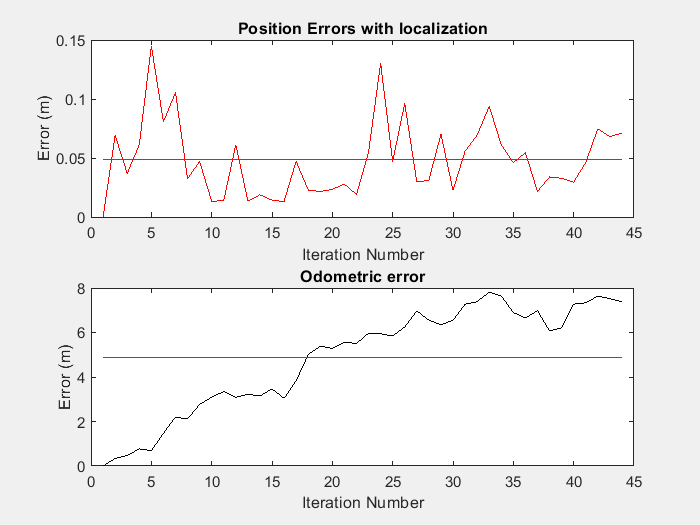

% 21 show average errors and their evolution.
avg_loc_error = mean(loc_error);
avg_odo_error = mean(odo_error);

figure(2);
set(gcf,'Visible','on');
subplot(211); 
plot(loc_error,'r'); 
hold on; 
line([1 size(loc_error,1)],[avg_loc_error avg_loc_error]); 
title('Position Errors with localization');
xlabel('Iteration Number');
ylabel('Error (m)');

subplot(212); 
plot(odo_error,'k'); 
hold on; 
line([1 size(loc_error,1)],[avg_odo_error avg_odo_error]); 
title('Odometric error');
xlabel('Iteration Number');
ylabel('Error (m)');